Part 1. Read the files, determine the starting time (Get Stage Zero Position).

NB! If error while running, most probably there are extra files in the dir!

This part is RUN WITH ALL THE FILES: both references and samples, and for all of the modulation frequencies.

clear all;


flagCompensateZeroOffsetInRatio = false;
% << when true, the script will subtract the ratio values averaged over the
% << first points
myPointsToComputeTheOFFSET = 5;
% << subtract the mean value over first # points
% << from the 'ratio' data.

flagUsePreDefinedStageZeroPosition = false;
predefStageZeroPos = -11200; % in steps; later is converted to the delay time.
% use example:
% Data.tdelay = (Data.stagePosition - Data.stagePosition(az_idx)).*(2*(12.5e-6)*(1e12))./2.99792458e8; %in ps
% <<<




%% Enter the path (<tmpDir>) to the folder with the data files: %%

% opt.1:
% tmpDir = pwd;

% opt.2:
% myDataDir = '\data';    % enter manually
% tmpDir = strcat( tmpDir, myDataDir );

% opt.3:
tmpDir = 'Z:\ForMATLAB\data';


fNames = dir(strcat(tmpDir, '\*.mat')) ;   % you are in the folder of files 
fprintf("\nTotal *.mat-files in 'data' folder:\n%d.\n",length(fNames))


Total *.mat-files in 'data' folder:
4.





% get zero time - "AZ" for "approximate zero":
tmpAZ = zeros(length(fNames),1); % value of the derivative in V_in
tmpAZind = zeros(length(fNames),1); % index
tmpAZtime = zeros(length(fNames),1); % value of the delay time.
tmpAZstagePos = zeros(length(fNames),1); % stage position.

for currFileN = 1:length(fNames)
    filename = fNames(currFileN).name;

    % data = load(strcat(tmpDir,'\',filename));
    % data = data.Data;
    % 
    % if isstruct(data)
    %     structData = struct();
    %     structData.stagePosition = data.stagePosition;%.Data(:,1);
    %     structData.tdelay = data.tdelay; %.Data(:,2); % in ps
    %     structData.Vin = data.Vin; %.Data(:,3); %in uV
    %     structData.Vout = data.Vout; %.Data(:,4); % in uV
    %     structData.Ratio = data.Ratio; %.Data(:,5);
    %     structData.Vdet = data.Vdet;
    % 
    %     Data = structData;
    % 
    % elseif ismatrix(data)
    %     Data.stagePosition = data(:,1);
    %     Data.tdelay = data(:,2);
    %     Data.Vin = data(:,3);
    %     Data.Vout = data(:,4);
    %     Data.Ratio = data(:,5);
    %     Data.Vdet = ones(length(data.Data(:,5)),1);
    % end
    % upd. 10.11.2023: >> %
    Data = ImportTDTRdataFromFile(strcat(tmpDir,'\',filename));
    % <<< %

    
    % Remove NaN values:  >>>>> %
    
    % %%% Apr. 19 >>> %%%
    % % Remove 'NaN' values: %
    % tmpBefore = length(Data.stagePosition);
    % Data = struct2table(Data);
    % Data = Data(~any(ismissing(Data),2),:);
    % Data = table2struct(Data,'ToScalar',true);
    % tmpAfter = length(Data.stagePosition);
    % fprintf("Deleted %d entries for file No. %d.\n", round(tmpBefore-tmpAfter),currFileN);
    % %%% <<< %%%
    % upd. 10.11.2023: >> %
    fprintf("For file No. %d: ",currFileN);
    Data = RemoveNaNfieldsFromTheStruct(Data, true); % second argument: print the output or not
    fprintf("\n");
    % <<< %
    
    % <<<<< Remove NaN values. %



    % upd. 10.11.2023: it is not needed here...
    % commenting it out. >>>>> %

    %% 01.08.2023 : subtract constant signal (offset) in the 'Ratio':
    % >>> %
    % tmpOffset = mean(Data.Ratio(1:myPointsToComputeTheOFFSET));
    % % fprintf("Computed offset: %f.",tmpOffset);
    % Data.Ratio = (Data.Ratio - tmpOffset);
    % <<< %

    % <<<<< %
    
    %% automatically shift the tdelay zero to peak position
    [tmpAZ(currFileN), tmpAZind(currFileN)] = max(abs(diff(Data.Vin)));
    tmpAZtime(currFileN) = Data.tdelay(tmpAZind(currFileN));
    tmpAZstagePos(currFileN) = Data.stagePosition(tmpAZind(currFileN));
end    % for currFind = 1:length(fNames)

For file No. 1: 

Deleted 1 entry.

For file No. 2: 

Deleted 1 entry.

For file No. 3: 

Deleted 1 entry.

For file No. 4: 

Deleted 1 entry.


fprintf('The value of the derivative in "Data.Vin" ("tmpAZ"):\n[%s]\n', join(string(tmpAZ), ','));

The value of the derivative in "Data.Vin" ("tmpAZ"):
[0.75522,0.91058,0.7058,0.29338]


fprintf('(mean value: %10.3f)',mean(tmpAZ));

(mean value:      0.666)


fprintf('Index of the zero delay element("tmpAZind"):\n[%s]\n', join(string(tmpAZind), ','));

Index of the zero delay element("tmpAZind"):
[31,31,31,32]


fprintf('(mean value: %10.2f)',mean(tmpAZind));

(mean value:      31.25)

fprintf('Time delay value at zero ("tmpAZtime"):\n[%s]\n', join(string(tmpAZtime), ','));

Time delay value at zero ("tmpAZtime"):
[0,0,0,0]


fprintf('(mean value: %10.3f)',mean(tmpAZtime));

(mean value:      0.000)

fprintf('Delay stage coordinate at zero ("tmpAZstagePos"):\n[%s]\n', join(string(tmpAZstagePos), ','));

Delay stage coordinate at zero ("tmpAZstagePos"):
[-11200,-11200,-11200,-11195]


fprintf('(mean value: %10.2f)',mean(tmpAZstagePos));

(mean value:  -11198.75)


% fprintf('File names: \n%s\n', join(string({fNames.name}),','));
fprintf('File names: \nNo.  StageZero   name\n');

File names: 
No.  StageZero   name


for currFileN = 1:length(fNames)
   fprintf('%d %f %s\n', currFileN, tmpAZstagePos(currFileN), fNames(currFileN).name);
end

1 -11200.000000 RefAuGlass1MHz@1MHz_011123_210559.mat
2 -11200.000000 RefAuGlass2MHz@2MHz_011123_205603.mat
3 -11200.000000 RefAuGlass5MHz@5MHz_011123_211534.mat
4 -11195.000000 RefSiO2_80nmAl_2MHz@2MHz_011123_214921.mat


fprintf('\n');
% we will use the stage position, and then re-calculate manually
% the delay time.
% There is a flag above, whether or not to use a given
%   stage coordinate corresponding to the zero delay time.

If the above output is consistent, get the mean shifted value

You can now update the pre-defined zero value in the beginning.

UPD. 09.11.2023 >> use the stage position value, instead...


%% OBSOLETE: >>> %%

% option 1:
% tmpMEANdelayINDEX = mean(tmpAZind)
% option 2:
% tmpMEANdelayINDEX = 28; % <<< override, if needed. %


%% WHY THIS CYCLE?!? Should be deleted, I believe... %
% tmpMEANdelayINDEX = round(tmpMEANdelayINDEX)
%if tmpMEANdelayINDEX < 1
%    tmpMEANdelayINDEX = 1;
%end
%while tmpMEANdelayINDEX > length(Data.stagePosition)
%    tmpMEANdelayINDEX = tmpMEANdelayINDEX - 1;
%end
%
%% <<< WHY THE CYCLE ?!? %%

%% <<< OBSOLETE %%

%% NEW: >>>>> %%

fprintf("\n\nComputing the zero stage position value: >>>\n");



Computing the zero stage position value: >>>



globStageZeroPos = 0;
if (flagUsePreDefinedStageZeroPosition)
    globStageZeroPos = predefStageZeroPos;
    fprintf("Using pre-defined stage zero position value of %f.\n", globStageZeroPos)
else
    globStageZeroPos = mean(tmpAZstagePos);
    fprintf("Taking the average  %f.\n", globStageZeroPos)
end

Taking the average  -11198.750000.



% use example:
% Data.tdelay = (Data.stagePosition - globStageZeroPos).*(2*(12.5e-6)*(1e12))./2.99792458e8; %in ps

fprintf("<<<");

<<<


%% <<<<< NEW. %%

PART 2. Get the correct lock-in phase. (AutoPhase routine.)

NOW RE-LOADING THE DATA ONCE AGAIN - THE DATA MIGHT HAVE CHANGED!

For this block to work, one should already have the value of <globStageZeroPos>.

The time delay will be subtracted when passing the data to the AutoSetPhase function (below):

tAutoPhaseMin = -20; % ps % counted from the <globStageZeroPos> position. 
tAutoPhaseMax = +80; % ps
fprintf("Using the following window around the <globStageZeroPos> position for phase auto setting: %f to %f.", ...
    tAutoPhaseMin,tAutoPhaseMax);

Using the following window around the <globStageZeroPos> position for phase auto setting: -20.000000 to 80.000000.

data = 1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN
   -1.1600   -0.0033    0.0001   -0.0001    0.0001    0.0260
   -1.1570   -0.0031    0.0001   -0.0001    0.0001    0.0260
   -1.1540   -0.0028    0.0001   -0.0001    0.0001    0.0260
   -1.1510   -0.0026    0.0001   -0.0001    0.0001    0.0260
   -1.1480   -0.0023    0.0001   -0.0001    0.0001    0.0260
   -1.1450   -0.0021    0.0001   -0.0001    0.0001    0.0260
   -1.1420   -0.0018    0.0001   -0.0001    0.0001    0.0260
   -1.1390   -0.0016    0.0001   -0.0001    0.0001    0.0260
   -1.1360   -0.0013    0.0001   -0.0001    0.0001    0.0260


Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: 0.00 degrees
 mean difference between [-20 0] and [0 80] ps: 0.089

residual = 4.994e-08, delphase = 2.6493

Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: -9.30 degrees
 mean difference between [-20 0] and [0 80] ps: -0.000



exporting file to:
Z:\ForMATLAB\data\RefAuGlass1MHz@1MHz_011123_210559_Inpt4AutoPhase_SHIFTED.mat


File No. -9.299188e+00: auto-phase shift == 

data = 1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN
   -1.1600   -0.0033    0.0001   -0.0001    0.0001    0.0260
   -1.1570   -0.0031    0.0001   -0.0001    0.0001    0.0260
   -1.1540   -0.0028    0.0001   -0.0001    0.0001    0.0260
   -1.1510   -0.0026    0.0001   -0.0001    0.0001    0.0260
   -1.1480   -0.0023    0.0001   -0.0001    0.0001    0.0260
   -1.1450   -0.0021    0.0001   -0.0001    0.0001    0.0260
   -1.1420   -0.0018    0.0001   -0.0001    0.0001    0.0260
   -1.1390   -0.0016    0.0001   -0.0001    0.0001    0.0260
   -1.1360   -0.0013    0.0001   -0.0001    0.0001    0.0260


Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: 0.00 degrees
 mean difference between [-20 0] and [0 80] ps: 0.021

residual = 2.8986e-07, delphase = 2.3671

Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: -1.84 degrees
 mean difference between [-20 0] and [0 80] ps: 0.000



exporting file to:
Z:\ForMATLAB\data\RefAuGlass2MHz@2MHz_011123_205603_Inpt4AutoPhase_SHIFTED.mat


File No. -1.842875e+00: auto-phase shift == 

data = 1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN
   -1.1600   -0.0033    0.0000   -0.0001    0.0000    0.0259
   -1.1570   -0.0031    0.0000   -0.0001    0.0001    0.0259
   -1.1540   -0.0028    0.0000   -0.0001    0.0000    0.0259
   -1.1510   -0.0026    0.0000   -0.0001    0.0000    0.0259
   -1.1480   -0.0023    0.0000   -0.0001    0.0000    0.0259
   -1.1450   -0.0021    0.0000   -0.0001    0.0000    0.0259
   -1.1420   -0.0018    0.0000   -0.0001    0.0000    0.0259
   -1.1390   -0.0016    0.0000   -0.0001    0.0001    0.0259
   -1.1360   -0.0013    0.0000   -0.0001    0.0000    0.0259


Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: 0.00 degrees
 mean difference between [-20 0] and [0 80] ps: 0.084

residual = 1.0713e-07, delphase = 2.659

Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: -9.19 degrees
 mean difference between [-20 0] and [0 80] ps: -0.000



exporting file to:
Z:\ForMATLAB\data\RefAuGlass5MHz@5MHz_011123_211534_Inpt4AutoPhase_SHIFTED.mat


File No. -9.190938e+00: auto-phase shift == 

data = 1.0e+04 *

       NaN       NaN       NaN       NaN       NaN       NaN
   -1.1600   -0.0033    0.0000   -0.0001    0.0000    0.0235
   -1.1570   -0.0031    0.0000   -0.0001    0.0000    0.0235
   -1.1540   -0.0028    0.0000   -0.0001    0.0001    0.0235
   -1.1510   -0.0026    0.0000   -0.0001    0.0001    0.0235
   -1.1480   -0.0023    0.0000   -0.0001    0.0000    0.0235
   -1.1450   -0.0021    0.0000   -0.0001    0.0000    0.0235
   -1.1420   -0.0018    0.0000   -0.0001    0.0001    0.0235
   -1.1390   -0.0016    0.0000   -0.0001    0.0000    0.0235
   -1.1360   -0.0013    0.0000   -0.0001    0.0000    0.0235


Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: 0.00 degrees
 mean difference between [-20 0] and [0 80] ps: 0.035

residual = 3.2038e-07, delphase = 4.334

Working with raw V(out)
 V(out) fit parameters y = mx + b: m = 000 uV/ps, b = 0.00 uV
 Total phase shift applied: -3.06 degrees
 mean difference between [-20 0] and [0 80] ps: 0.000



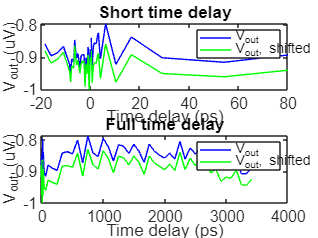

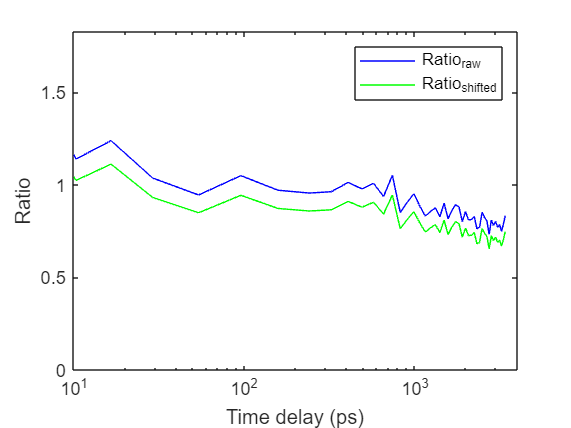

exporting file to:
Z:\ForMATLAB\data\RefSiO2_80nmAl_2MHz@2MHz_011123_214921_Inpt4AutoPhase_SHIFTED.mat


File No. -3.055125e+00: auto-phase shift == 


arrNewFiles = strings(length(fNames),1);    % these files are created for feeding the pre-processed
% data to the <AutoPhase> routine.
phaseShiftsAutoApplied = zeros(length(fNames),1);   % the output of the <AutoPhase> routine.


for currFileN = 1:length(fNames)
    filename = fNames(currFileN).name;
    
    % upd. 10.11.2023: >> %
    Data = ImportTDTRdataFromFile(strcat(tmpDir,'\',filename));
    % <<< %
    

    % Remove NaN values:  >>>>> %
    fprintf("For file No. %d: ",currFileN);
    Data = RemoveNaNfieldsFromTheStruct(Data, true); % second argument: print the output or not
    fprintf("\n");
    % <<<<< Remove NaN values. %

    
    %% USE THE MANUAL (SINGLE) SHIFT FOR THE ZERO POS
    % Data.tdelay = (Data.stagePosition - Data.stagePosition(tmpMEANdelayINDEX)).*(2*(12.5e-6)*(1e12))./2.99792458e8; %in ps
    % upd. 10.11.2023:  >>>>> %
    Data.tdelay = (Data.stagePosition - globStageZeroPos).*(2*(12.5e-6)*(1e12))./2.99792458e8; %in ps
    % <<<<< %
    

    % Plotting is removed from here %
    

    % upd. 10.11.2023:  >>>>> %
    % This file is needed to run the auto-phase routine on it:
    
    prefix = strsplit(filename,'.');
    arrNewFiles(currFileN) = [prefix{1} '_Inpt4AutoPhase.mat'];
    tmp = strcat(tmpDir, '\', arrNewFiles(currFileN));
    save(tmp,"Data");
    
    % new_file = [prefix{1} '_prep.mat'];
    % save(new_file,"Data")
    
    % <<<<< %
    
    
    %%Automatically run AutoSetPhase() to fix phase shift emerging from
    %%instrumentation
    
    phaseCurr = 0.0;    % degrees % for <AutoSetPhase> output...
    % AutoSetPhase(0, arrNewFiles(currFind),[-20 80])
    [notUsed1, phaseCurr, notUsed2] = AutoSetPhase( 0, convertStringsToChars(tmp), [tAutoPhaseMin tAutoPhaseMax]);
    % the output for <phaseCurr> is in degrees. %

    phaseShiftsAutoApplied(currFileN) = phaseCurr;
    if (true)
        fprintf("File No. %d: auto-phase shift == %8.3f (deg.)\n",phaseCurr)
    end


    % Delete temporary files created in this script:
    if exist(tmp, 'file')==2    % 2 == file
        delete(tmp)
        % fprintf("%d : deleted a temp file.",currFileN)
    %else
        %fprintf("%d : Not a temp file.",currFileN)
    end

end    % for currFind = 1:length(fNames)


    
% Delete temp. files created in the <AutoPhase> routine:
tmpFileNames = dir(strcat(tmpDir, '\*_SHIFTED.mat')) ;   % you are in the folder of files 

for currFileN = 1:length(tmpFileNames)
    tmp = tmpFileNames(currFileN).name;
    tmp = strcat(tmpDir, '\', tmp);

    if exist(tmp, 'file')==2    % 2 == file
        delete(tmp)
        % fprintf("%d : deleted a temp file from 'AutoPhase'.",currFileN)
    %else
        % fprintf("%d : Not deleted a temp file from 'AutoPhase'.",currFileN)
    end

end

fprintf("Done!");

Done!

Now, check the phase shifts:

% upd. 10.11.2023:
fprintf("Phase values obtained in the previous\nstep from the AutoPhase routine:\n");

Phase values obtained in the previous
step from the AutoPhase routine:


fprintf("No.  phaseAuto  file name");

No.  phaseAuto  file name

for currFileN = 1:length(fNames)
    fprintf("%d   %0.4f   %s\n",currFileN, phaseShiftsAutoApplied(currFileN), fNames(currFileN).name)
end

1   -9.2992   RefAuGlass1MHz@1MHz_011123_210559.mat
2   -1.8429   RefAuGlass2MHz@2MHz_011123_205603.mat
3   -9.1909   RefAuGlass5MHz@5MHz_011123_211534.mat
4   -3.0551   RefSiO2_80nmAl_2MHz@2MHz_011123_214921.mat



fprintf("Mean phase shift: %f.\n",mean(phaseShiftsAutoApplied));

Mean phase shift: -5.847031.


IMPORTANT!

Choose the phase shift to be applied:  >>>>>

flagUseCustomPhaseShift = false; %if false, using the mean of <phaseShiftsAutoApplied>.
decidedCustomPhaseShiftDEG = 0.00; % degrees

if (flagUseCustomPhaseShift)
    phaseToUse = decidedCustomPhaseShiftDEG; % degrees
    fprintf("OK, let's use a custom phase shift.\n")
else
    phaseToUse = mean(phaseShiftsAutoApplied); % degrees
    fprintf("Using the mean of the <AutoPhase> output.\n")
end

Using the mean of the <AutoPhase> output.


fprintf("<phaseToUse> = %0.4f degrees.",phaseToUse);

<phaseToUse> = -5.8470 degrees.

STOPPED AT...

PART 3. Final.

Use the obtained above values of <globStageZeroPos> and <phaseToUse> to manually apply the phase shifts and time shift.

+ output for further processing.

for currFileN = 1:length(fNames)

    filename = fNames(currFileN).name;

    % upd. 10.11.2023: >> %
    Data = ImportTDTRdataFromFile(strcat(tmpDir,'\',filename));
    % <<< %


    % Remove NaN values:  >>>>> %
    fprintf("For file No. %d: ",currFileN);
    Data = RemoveNaNfieldsFromTheStruct(Data, true); % second argument: print the output or not
    fprintf("\n");
    % <<<<< Remove NaN values. %
    

    %% USE THE MANUAL (SINGLE) SHIFT FOR THE ZERO POS
    % upd. 10.11.2023:  >>>>> %
    Data.tdelay = (Data.stagePosition - globStageZeroPos).*(2*(12.5e-6)*(1e12))./2.99792458e8; %in ps
    % <<<<< %


    %% SETTING THE PHASE MANUALLY:
    [Data.Vin, Data.Vout] = VKorn_PhaseShift(phaseToUse, ...
        Data.Vin, Data.Vout);
    Data.Ratio = - Data.Vin ./ Data.Vout;

    

    %% STOPPED AT ... %%
    


    prefix = strsplit(filename,'.');
    % ALREADY DEFINED ABOVE: 
    % arrNewFiles(currFind) = [prefix{1} '_prep.mat'];
    tmp = strcat(tmpDir, '\', arrNewFiles(currFind));
    
    % ALREADY SAVED ABOVE:
    % save(tmp,"Data");
    % new_file = [prefix{1} '_prep.mat'];
    % save(new_file,"Data")
    
    tmp = strcat(prefix{1}, '_FIN.mat');
    tmp = strcat(tmpDir, '\', tmp);
    
    % 20.06.2023:
    % remove NaNs again (no idea why):
    % Remove 'NaN' values: %
    tmpBefore = length(Data.stagePosition);
    Data = struct2table(Data);
    Data = Data(~any(ismissing(Data),2),:);
    Data = table2struct(Data,'ToScalar',true);
    tmpAfter = length(Data.stagePosition);
    fprintf("Deleted %d entries for file No. %d.\n", round(tmpBefore-tmpAfter),currFind);
    %%% <<< %%%
    
    save(convertStringsToChars(tmp),"Data")
    
    filename_short = (strsplit(tmp, '.mat')); % take filename w/o extension
    filename_short = string(filename_short(1));
    filename_short = strcat(filename_short, ".dat");

    writetable(struct2table(Data), filename_short);

end    % for currFind = 1:length(fNames)

fprintf("Done (setting manual phase)!");

Plotting:

%%%
figure;
subplot(3,1,1)
plot(Data.tdelay,Data.Vin)
ylabel('V_{in}')
xlabel('t_{delay}')
subplot(3,1,2)
plot(Data.tdelay,Data.Vout)
ylabel('V_{out}')
xlabel('t_{delay}')
subplot(3,1,3)
plot(Data.tdelay,Data.Ratio)
ylabel('Ratio')
xlabel('t_{delay}')
%%%

..

%